作异形彩色标记线条图

## 语法

## 示例

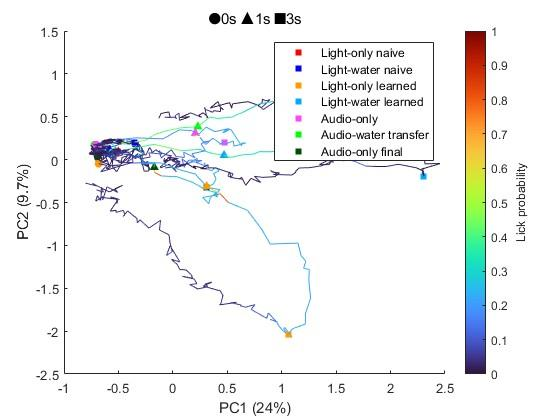

## 输入参数

Lines(:,2)table， 线上采样点的坐标、颜色和标记颜色信息。颜色信息一律使用[0,1]范围内的(1,3)double三元行向量，依次给出RGB通道值。每行一条线，必需包含以下列：

- PointColors(:,5:6,:)，每个采样点的坐标和颜色，第2维XYRGB或XYZRGB，第3维时间，根据是否提供Z决定画3D还是2D图。

- MarkerColor(:,3)，每条线上使用的标记颜色，不同线上颜色不同，一条线上颜色相同。第2维RGB。

Markers(:,2)table，每个标记的位置和形状，每行对应一个标记。必需包含以下列：

- Index(:,1)uint16，标记时点位置，将在每条线的该时点上添加一个标记。这里的时点是采样时点索引，不是真实时间。通常需要用真实时间×采样率。

- Shape(:,1)char，标记符号形状。此功能依赖scatter或scatter3实现，详见Scatter.Marker属性文档。

### 名称值参数

PatchArguments(1,:)cell，额外传递给patch的名称值参数。本函数调用patch绘制渐淡线条，此处传递额外参数以控制线条样式细节。

ScatterArguments(1,:)cell，额外传递给scatter或scatter3的名称值参数。本函数调用scatter或scatter3绘制符号标注，此处传递额外参数以控制标注样式细节。

## 返回值

Scatters(:,:)matlab.graphics.chart.primitive.Scatter，对每个标记返回一个Scatter对象，第1维对应不同的线，第2维对应不同时点（亦即不同形状）的标记。

**See also **[patch](matlab:doc patch) [scatter](matlab:doc scatter) [scatter3](matlab:doc scatter3) [matlab.graphics.chart.primitive.Scatter](matlab:doc matlab.graphics.chart.primitive.Scatter) [matlab.graphics.primitive.Patch](matlab:doc matlab.graphics.primitive.Patch)

function Scatters = ColorfulMarkerPlot(Lines,Markers,options)
arguments
	Lines
	Markers
	options.PatchArguments={}
	options.ScatterArguments={}
end
PointColors=permute(Lines.PointColors,[3,1,2]);
[NumLines,NumDimensions]=size(PointColors,2,3);
NumDimensions=NumDimensions-3;
PointColors(end+1,:,:)=NaN;
Points=PointColors(:,:,1:NumDimensions);
PointCells=num2cell(Points,1:2);
patch(PointCells{:},PointColors(:,:,NumDimensions+1:end),options.PatchArguments{:},EdgeColor='flat',FaceColor='none');
HoldState=ishold;
hold on;
NumShapes=height(Markers);
Scatters=gobjects(NumLines,NumShapes);
Points=Points(Markers.Index,:,:);
MarkerColors=Lines.MarkerColor;
for S=1:NumShapes
	for L=1:NumLines
		switch NumDimensions
			case 2
				Scatters(L,S)=scatter(Points(S,L,1),Points(S,L,2),Markers.Shape(S),options.ScatterArguments{:},MarkerEdgeColor='none',MarkerFaceColor='flat',CData=MarkerColors(L,:));
			case 3
				Scatters(L,S)=scatter3(Points(S,L,1),Points(S,L,2),Points(S,L,3),Markers.Shape(S),options.ScatterArguments{:},MarkerEdgeColor='none',MarkerFaceColor='flat',CData=MarkerColors(L,:));
			otherwise
				UniExp.UniExpException.Point_coordinates_must_have_2_or_3_dimensions.Throw(NumDimensions);
		end
	end
end
if ~HoldState
	hold off;
end